# Show renders from our lenses

This script allows you to visualize in advance how a scene will render through some or all of our current lenses for a user-selected sensor size. By default it will use all of the lens files in your path, but you can filter for those containing a specific string in their name.

Dependencies: ISET3d-v4, ISETCam, isetlens

D. Cardinal, 2022

Note: For expediency, we have pre-generated several possible variations of scene and sensor size and placed them as HTML files in the previews sub-folder.

## Initialize ISET and Docker

ieInit;
if ~piDockerExists, piDockerConfig; end

## Choose Options

sensorSize =6; % (diagonal in mm)
useScene = 'chessSet'; % one of our default scenes
raysPerPixel = 96;
sensorResolution = 400;
% optionally only render matching lenses
lensNameFilter = "";

fprintf('Lens Inventory using Scene: %s\n', useScene);

Lens Inventory using Scene: chessSet


fprintf('Sensor Size: %d, rayPP %d, resolution %d\n',...
    sensorSize,raysPerPixel,sensorResolution);

Sensor Size: 6, rayPP 96, resolution 400


## Read the selected Scene and add a Light

thisR  = piRecipeDefault('scene name',useScene);

Read 9 materials.
Read 3 textures.
***Scene parsed.


lightName = 'from camera';
ourLight = piLightCreate(lightName,...
    'type','distant',...
    'cameracoordinate', true);
recipeSet(thisR,'lights', ourLight,'add');

## Set render quality

% Set resolution for speed or quality.
thisR.set('film resolution',[sensorResolution sensorResolution]);  % 2 is high res. 0.25 for speed
thisR.set('rays per pixel',raysPerPixel);                      % 128 for high quality

% Pick out a bit of the image to look at.  Middle dimension is up.
% Third dimension is z.  For the chess set we use a from/to that put the ruler in the
% middle.  The in focus is about the pawn or rook.
switch(useScene)
    case 'chessSet'
        thisR.set('from',[0 0.14 -0.7]);     % Get higher and back away than default
        thisR.set('to',  [0.05 -0.07 0.5]);  % Look down default compared to default
    case 'cornell_box'
        %
end
%thisR.set('aperture diameter',1);   % thisR.summarize('all');

## Determine the range of object depths in our scene

Note: Getting depth will use pinhole optics, but we use an omni camera with lenses for the rest.

depthRange = thisR.get('depth range');

*** Rendering time for ChessSet:  8.2 sec ***

exr2bin done.

%depthRange = [0.1674, 3.3153];  % Chess set distances in meters

## Create cameras that use each lens

We get a list of all our lenses, then iterate over it creating a camera object using that lens, and render the same scene through each of them.

allLensFiles = lensC.list('quiet', true);
if ~isempty(lensNameFilter)
    lensNames = {allLensFiles.name};
    lensIdx = contains(lensNames,lensNameFilter);
    lensFiles = allLensFiles(lensIdx);
else
    lensFiles = allLensFiles;
end
images = []; % our output images
for ii = 1:numel(lensFiles)
    lensFileName = lensFiles(ii).name;
    lensFile = fullfile(lensFiles(ii).folder, lensFileName);
    fprintf('Using lens #%d: %s\n',ii, lensFile);
    thisR.camera = piCameraCreate('omni','lensFile',lensFile);
    thisR.set('focal distance',mean(depthRange));
    
    % depending on the film size we'll get
    % different fields of view
    thisR.set('film diagonal',sensorSize);

## Render and display

Using lens #47: C:\iset\isetlens\data\lens\wide.77deg.4.38mm.json


*** Rendering time for ChessSet:  10.3 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\wide.77deg.4.38mm.json


Read 2 materials.
Read 0 textures.
***Scene parsed.
*** Rendering time for flatSurface:  7.9 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\wide.77deg.4.38mm.json


Render Camera 1 position 1
Scene will not be parsed. Maybe we can parse in the future
Read 0 materials.
Read 0 textures.
***Scene parsed.


*** Rendering time for stepfunction:  8.8 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\wide.77deg.4.38mm.json
Render Camera 1 position 2
Scene will not be parsed. Maybe we can parse in the future
Read 0 materials.
Read 0 textures.
***Scene parsed.


*** Rendering time for stepfunction:  8.8 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\wide.77deg.4.38mm.json
Render Camera 1 position 3
Scene will not be parsed. Maybe we can parse in the future
Read 0 materials.
Read 0 textures.
***Scene parsed.


*** Rendering time for stepfunction:  8.7 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\wide.77deg.4.38mm.json


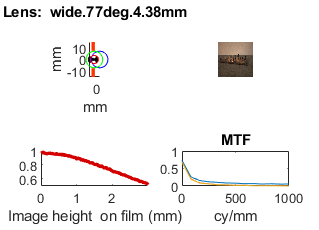

    piWrite(thisR);
    
    try
        oi = piRender(thisR,'render type',{'radiance', 'depth'});
        oi = oiSet(oi,'name',sprintf('Lens: %s  and %d mm sensor',...
            lensFileName, sensorSize));
        % get a viewable version of our optical image:
        img = oiShowImage(oi,-1);
        
        % Load our lens so we can view it
        lenses{ii} = lensC('filename', lensFile);
        
        % Set some headers per lens
        %fprintf('----------------------------\n');
        %fprintf('Rendered using: %s, with focal length: %05.1f',lensFileName,lenses{ii}.focalLength);
        
        % Draw a diagram of our lens into a subplot
        [~,fHdl] = lenses{ii}.draw([2,2,1]);
        
        images{ii} = img; % for creating a montage
        
        % Once the lens can draw into a subplot, we can show the sample
        % output next to it
        subplot(2,2,2);
        imshow(img,'Border','tight');
        
        % plot relative illuminance (into a subplot)
        piRelativeIlluminance("lensfile",lensFile,"figure",[2,2,3],...
            'sensorSize',sensorSize);

        % plot MTF
        %filmwidth_mm=0.01;
        filmwidth_mm=.01;
        [MTF, ~, ~] = piCalculateMTF('camera',thisR.camera,...
            'distances',[1000, 5000, 10000],...
            'resolution',2000,'rays',1000,...
            'filmwidth', sensorSize/1000);
        subplot(224);
        plot(MTF.cyclespermilimeter,MTF.MTF);
        xlabel('cy/mm');
        ylim([0 1]);
        xlim([0 1000]);
        title('MTF');

        % set plot attributes
        set(gcf,'Name',lensFileName,'MenuBar','none','ToolBar','none');

        drawnow; %doesn't seem to help, but who knows?
        % footer if using headers
        %fprintf('----------------------------\n');

    catch
        warning('Lens: %s failed to render.\n', lensFile);
    end
    
end

## Show a Captioned Montage for Reference

For filename captions to be legible we need to make sure we have enough room

minTileSize = 400; thumbnailSize = 400;
boxSize = max(minTileSize, sensorResolution);
textPosition = [10 10; boxSize-30 boxSize-30];
for ii = 1:numel(images)
    if minTileSize > sensorResolution && ~isempty(images{ii})
        imagesR{ii} = imresize(images{ii},[boxSize boxSize]);
    else
        imagesR{ii} = images{ii};
    end
    imagesC{ii} = insertText(imagesR{ii}, textPosition, lensFiles(ii).name, ...
        'FontSize', 36); %#ok<*SAGROW>
end
figure; % new figure below 
fprintf('Lens Inventory using Scene: %s\n', useScene);

Lens Inventory using Scene: chessSet


fprintf('Sensor Size: %d, rayPP %d, resolution %d\n',...
    sensorSize,raysPerPixel,sensorResolution);

Sensor Size: 6, rayPP 96, resolution 400


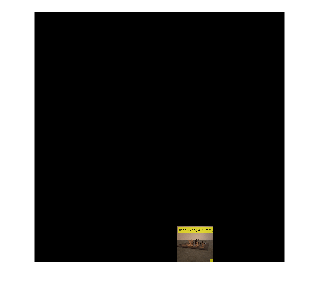

montage(imagesC,'ThumbnailSize',[thumbnailSize thumbnailSize]);